# Problemas con dos variables

En general, la mayoría de fenómenos físicos puede variar con muchos factores diferentes. Además, cuando se formulan problemas con dos variables, las dimensiones de la matriz deben concordar.

Considere lo siguiente:

x = 3;
y = 5;
A = x * y

Dado que **x** y **y** son escalares, el cálculo es sencillo.

Ahora considere esto:

x = 1:5;
A = x * y

En este caso, dado que **y** sigue siendo un escalar, únicamente se está multiplicando cada elemento de la matriz **x** por el escalar **y**.

Entonces, ¿qué pasaría si **y** es un vector?

y = 1:3;
A = x * y

Notemos que no es posible la multiplicación matricial (porque ***** es para el producto matricial, aunque tampoco sería posible multiplicar término a término con **.*** por la inconsistencia de las matrices) dándonos un error. 

Una forma de corregir este error sería utilizando la función `linspace`.

y = linspace(1,3,5);
A = x .* y

¿Pero es eso lo que se buscaba? Recordemos que el vector **y** era 

y el nuevo vector es **y** usando `linspace` es

que no es igual al vector **y** original. Por tanto, no es lo que se buscaba. El resultado

se lo puede entender más fácilmente en la siguiente tabla:

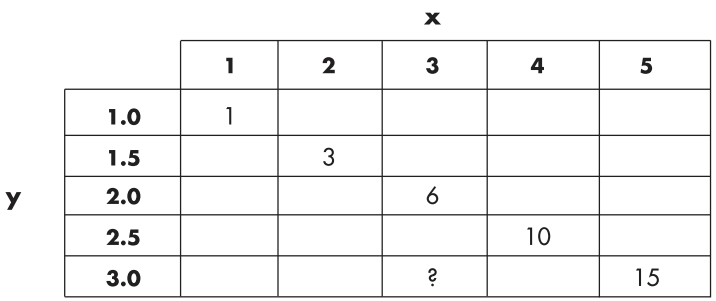

¿Pero qué pasaría si queremos el elemento 3 del vector **x** y el elemento 5 del vector **y**? Evidentemente este método no nos ayuda a obtenerlo.

Recordemos que buscamos la multiplicación término a término del vector `x = 1:5` con el vector `y = 1:3`, es decir, buscamos todas las combinaciones, o relaciones, de los elementos del vector **x** con el vector **y**.

Para este propósito nos es de gran utilidad la función `meshgrid` que se detalla a continuación.

## Función meshgrid

Esta función vendría a significar: *mapeo de vectores en un arreglo bidimensional*. En cristiano, relaciona cada elemento de un vector con cada elemento de otro vector.

Así pues, se puede utilizar esta función para mapear dos variables unidimensionales en variables bidimensionales de igual tamaño.

Continuando en donde nos quedamos, tenemos:

x = 1:5        % Vector fila.
y = 1:3        % Vector fila.
[new_x, new_y] = meshgrid(x,y)

La función `meshgrid` toma los dos vectores de entrada y crea dos matrices bidimensionales. Cada una de las matrices resultantes tiene el mismo número de filas y columnas.

- El número de columnas se determina por el número de elementos del vector **x**.

- El número de filas se determina por el número de elementos del vector **y**.

Entonces, si multiplicamos término a término `new_x` con `new_y` tendríamos la relación de cada elemento del vector **x** original con cada elemento del vector **y** original.

A = new_x .* new_y

A continuación se explica más detalladamente lo que hace internamente la función `meshgrid`.

### Explicación detallada de la función meshgrid

Retomando las líneas de código anteriores tenemos:

x = 1:5;        % Vector fila.
y = 1:3;        % Vector fila.
[new_x, new_y] = meshgrid(x,y)

Antes que nada, notemos que:

- `new_x` tiene las mismas filas repetidas (vector **x**) en función del tamaño del vector **y**.

- `new_y` tiene las mismas columnas repetidas (vector **y** transpuesto) en función del tamaño del vector **x**.

**Aclaración:** En realidad, más que transponer, MATLAB trabaja generalmente con columnas. Sin embargo, para `new_x` esto es imperceptible.

Para notar la diferencia, analice el siguiente ejemplo:

x1 = [          % Matriz mxn.
    1 2
    3 4
    5 6
    ];
y1 = [          % Matriz mxn.
    5 6
    7 8
    ];
[new_x1, new_y1] = meshgrid(x1,y1)

Como puede observar, para `new_x1` MATLAB toma la primera columna de la matriz **x1** y la vuelve fila `[1 3 5]`. A continuación, toma la segunda columna de la misma matriz y también la hace fila `[2 4 6]`. Finalmente une ambas filas `[1 3 5 2 4 6]` y las repite en función del número de elementos de la matriz **y1**.

Lo mismo ocurre para `new_y1` pero, en lugar de hacerlas fila, las deja como columnas y pone una debajo de otra. Luego repite las columnas en función del número de elementos de la matriz **x1**.

*Este proceso se puede hacer de forma indefinida y dependerá de cuán grande sean las matrices que se quiere relacionar.*

Al obtener estas nuevas matrices, `new_x1` y `new_y1`, como tienen las mismas dimensiones, es posible multiplicarlas elemento a elemento. La matriz resultante es la relación en cada elemento del vector **x1** con cada elemento del vector **y1**.

A = new_x1 .* new_y1

Una forma didáctica y visual de entenderlo, incluso para corroborar la respuesta, es realizar la siguiente tabla (similar a la que se mostró más arriba, pero con los valores verdaderos):

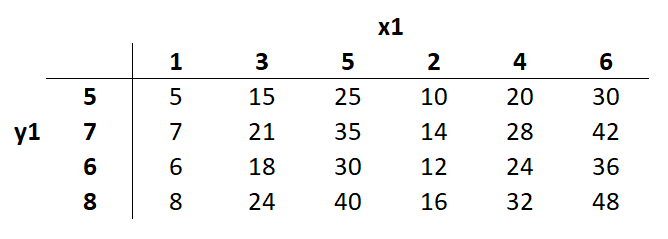

Así se verifica que cada elemento de la matriz **x1** se relaciona con cada elemento de la matriz **y1**.

**Nota:** Observe que para ordenar la matriz **x1** como vector fila y la matriz **y1** como vector columna se siguieron las especificaciones explicadas en esta aclaración.